%Test case Lagrange
xa = [-2 -1 1 2]

xa =     -2    -1     1     2


ya = [-6 0 0 6]

ya =     -6     0     0     6


x = 1.5

x = 1.5000

resultLagrange = Lagrange(xa, ya, x);

fprintf("Kết quả tại y(1.5) = %.4f", resultLagrange);

Kết quả tại y(1.5) = 1.8750

fprintf("Hàm số:  ");

Hàm số:  

P_Lagrange = LagrangeSymbolic(xa, ya);
fprintf("Hàm số Lagrange: %s\n", P_Lagrange);

Hàm số Lagrange: x^3 - x


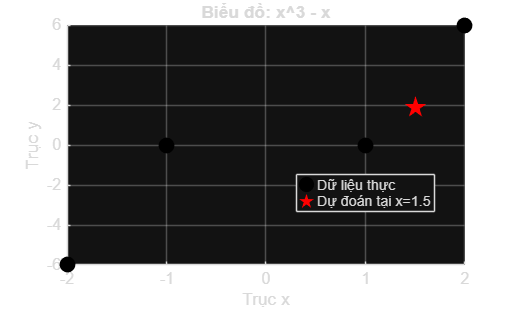

% --- PHẦN CODE VẼ ĐỒ THỊ (Thêm vào cuối bài) ---

figure('Name', 'Đồ thị Nội suy Lagrange', 'Color', 'w'); % Tạo cửa sổ mới
hold on; grid on; % Giữ đồ thị và hiện lưới

% 1. Vẽ các điểm dữ liệu đầu vào (xa, ya) - Màu đen, hình tròn
plot(xa, ya, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'Dữ liệu thực');

% 2. Vẽ đường cong đa thức nội suy từ biến P_Lagrange
try
    % Chuyển chuỗi ký tự (string) thành công thức toán (symbolic) để vẽ
    f_sym = str2sym(P_Lagrange); 
    
    % Dùng fplot để vẽ đường cong mượt mà
    fp = fplot(f_sym, [min(xa)-0.5, max(xa)+0.5]);
    fp.Color = 'b';        % Màu xanh dương
    fp.LineWidth = 1.5;    % Độ dày nét
    fp.DisplayName = 'Đa thức nội suy';
catch
    warning('Không thể vẽ đường cong. Kiểm tra lại biến P_Lagrange có phải là chuỗi công thức không.');
end

% 3. Vẽ điểm kết quả dự đoán (x, resultLagrange) - Màu đỏ, hình ngôi sao
plot(x, resultLagrange, 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r', 'DisplayName', ['Dự đoán tại x=' num2str(x)]);

% Trang trí đồ thị
xlabel('Trục x');
ylabel('Trục y');
title(['Biểu đồ: ' char(P_Lagrange)], 'Interpreter', 'none'); % Hiện phương trình lên tiêu đề
legend('Location', 'best'); % Hiện chú thích
hold off;

%Test case Newton
xa = [-2 -1 1 2]

xa =     -2    -1     1     2


ya = [-6 0 0 6]

ya =     -6     0     0     6


x = 1.5

x = 1.5000

resultNewton = NewtonInterpolation(xa, ya, x);
fprintf("Kết quả tại y(1.5) = %.4f", resultNewton);

Kết quả tại y(1.5) = 1.8750

fprintf("Hàm số:  ");

Hàm số:  

P_Newton = NewtonSymbolic(xa, ya)

$$P\_Newton = x^{3}-x$$